## divide train set and test set

data = X;
label = y;

% ratio = 0.75;
% num_train = floor(length(label)*ratio); 
% choose = randperm(length(label)); 

train_data  = data(choose(1:num_train), vsel_pso_spa);
train_label = label(choose(1:num_train));
test_data   = data(choose(num_train+1:end), vsel_pso_spa);
test_label  = label(choose(num_train+1:end));

tic
[bestacc0, bestc0, bestg0] = svm_gridsearch(train_label,...
                        train_data,-4, 2, -4, 2, 10, 1, 1, 0.2);
toc

*
optimization finished, #iter = 63
nu = 0.933333
obj = -7.749691, rho = -0.943329
nSV = 126, nBSV = 126
*
optimization finished, #iter = 66
nu = 0.956522
obj = -8.211507, rho = -0.979401
nSV = 132, nBSV = 132
*
optimization finished, #iter = 72
nu = 1.000000
obj = -8.982260, rho = 0.003600
nSV = 144, nBSV = 144
*
optimization finished, #iter = 63
nu = 0.976744
obj = -7.761399, rho = 0.941503
nSV = 126, nBSV = 126
*
optimization finished, #iter = 65
nu = 0.933333
obj = -7.667587, rho = 0.919278
nSV = 126, nBSV = 126
*
optimization finished, #iter = 67
nu = 0.956522
obj = -8.170689, rho = 0.967687
nSV = 132, nBSV = 132
Total nSV = 273
*
optimization finished, #iter = 62
nu = 0.932331
obj = -7.630522, rho = -0.947818
nSV = 124, nBSV = 124
*
optimization finished, #iter = 66
nu = 0.963504
obj = -8.212514, rho = -0.979412
nSV = 132, nBSV = 132
*
optimization finished, #iter = 71
nu = 1.000000
obj = -8.858702, rho = 0.004294
nSV = 142, nBSV = 142
*
optimization finished, #iter = 63
nu = 0.9

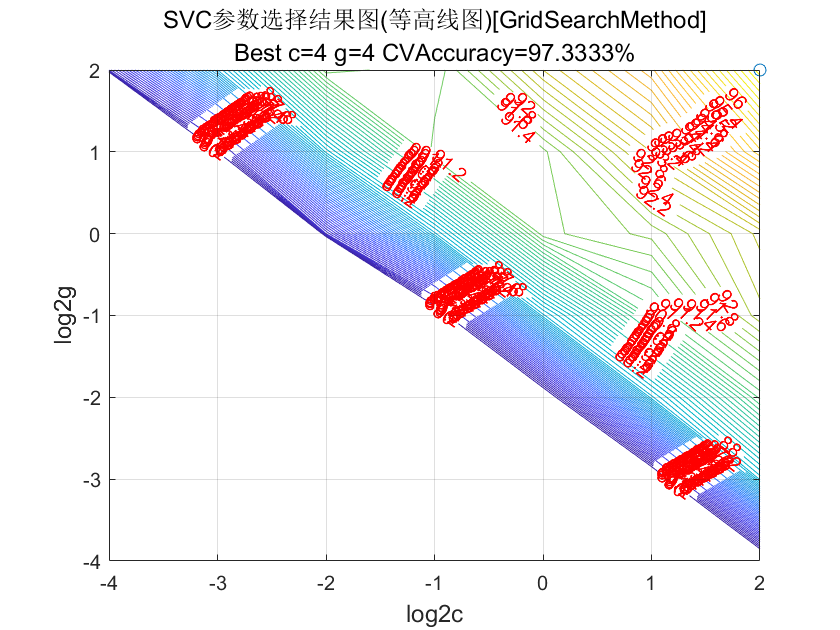

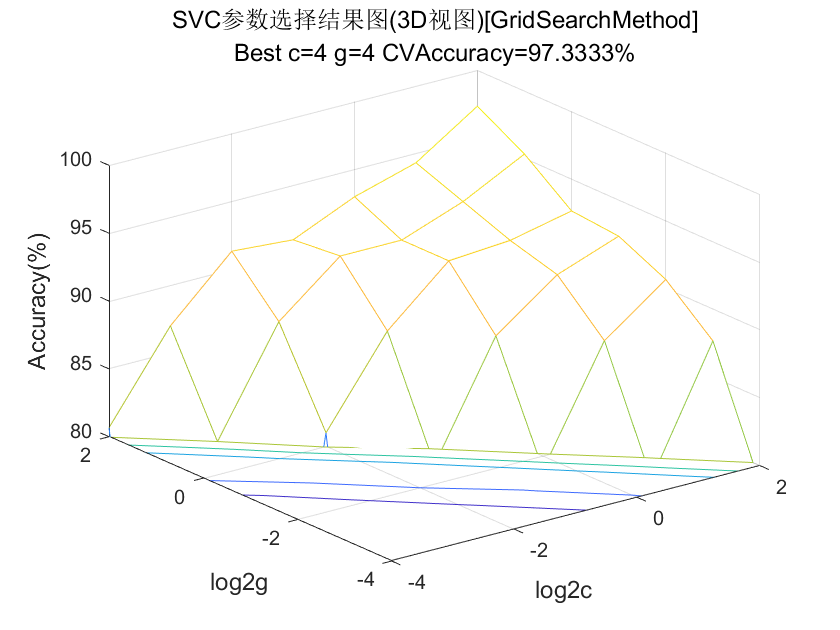

tic
[bestacc, bestc, bestg] = svm_gridsearch(train_label,...
                        train_data,0, 2, 0, 2, 10, 0.1, 0.1, 0.1);

toc

历时 3.086673 秒。


*
optimization finished, #iter = 39
nu = 0.392451
obj = -37.496971, rho = -0.057057
nSV = 56, nBSV = 51
*
optimization finished, #iter = 69
nu = 0.514713
obj = -44.060035, rho = 0.694374
nSV = 74, nBSV = 68
*
optimization finished, #iter = 66
nu = 0.783341
obj = -91.028810, rho = 0.072132
nSV = 115, nBSV = 111
*
optimization finished, #iter = 59
nu = 0.416379
obj = -33.334923, rho = 0.417773
nSV = 56, nBSV = 50
*
optimization finished, #iter = 28
nu = 0.260438
obj = -22.724046, rho = 0.162192
nSV = 36, nBSV = 32
*
optimization finished, #iter = 41
nu = 0.333333
obj = -26.976649, rho = -0.211763
nSV = 46, nBSV = 46
Total nSV = 204
*
optimization finished, #iter = 37
nu = 0.381757
obj = -35.756686, rho = -0.078390
nSV = 53, nBSV = 48
*
optimization finished, #iter = 50
nu = 0.529875
obj = -44.833999, rho = 0.719782
nSV = 74, nBSV = 69
*
optimization finished, #iter = 66
nu = 0.795263
obj = -90.208162, rho = 0.342694
nSV = 114, nBSV = 110
*
optimization finished, #iter = 49
nu = 0.405579


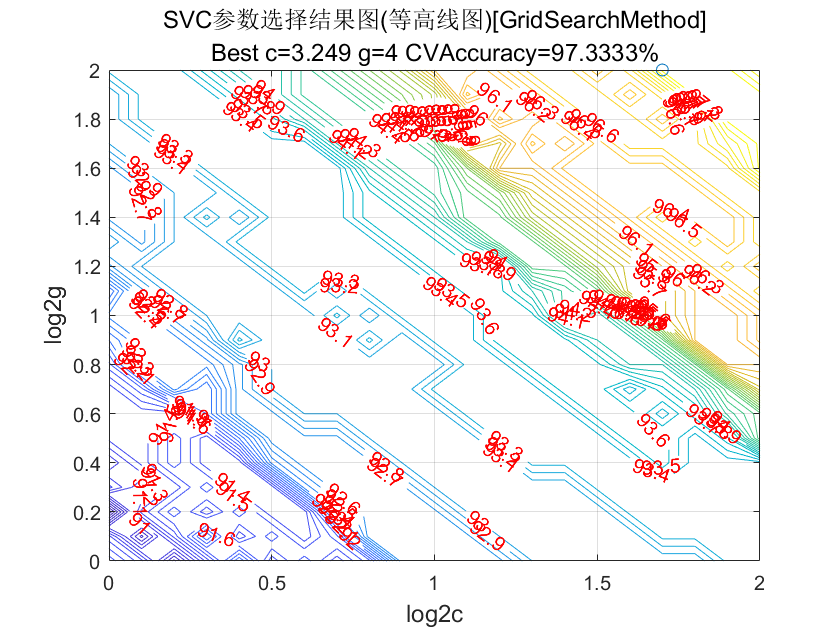

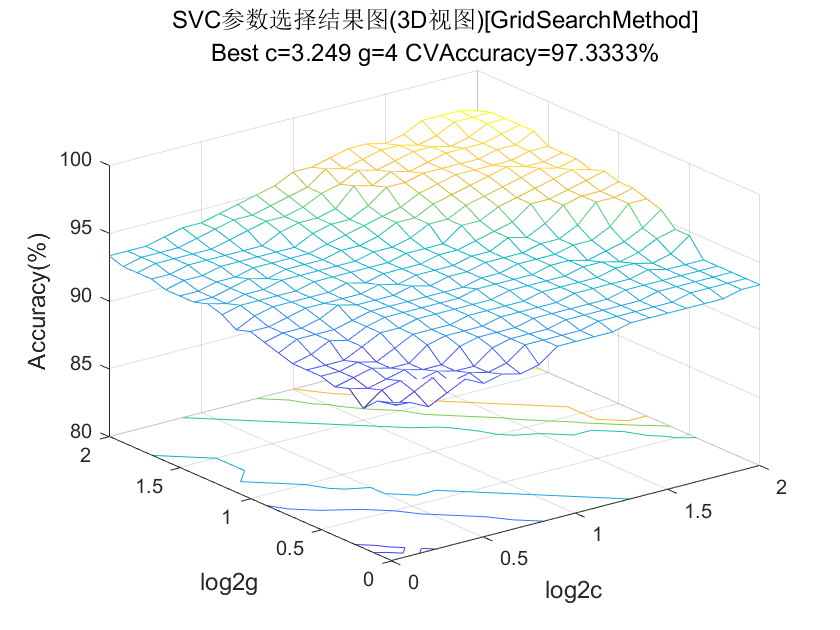

s = 0;
t = 0;
c = bestc;

g = bestg;

历时 23.235106 秒。


options = [' -s ',num2str(s),' -t ',num2str(t),' -c ',num2str(c),' -g ',num2str(g)]; 
model = libsvmtrain(train_label, train_data, options); 

[train_pred_label, train_acc, ~]...
           = libsvmpredict(train_label, train_data, model);
[test_pred_label, test_acc, ~]...
           = libsvmpredict(test_label, test_data, model);

*
optimization finished, #iter = 35
nu = 0.290588
obj = -113.067189, rho = -2.792316
nSV = 45, nBSV = 40
*
optimization finished, #iter = 82
nu = 0.348016
obj = -122.030645, rho = -0.272483
nSV = 56, nBSV = 50
*
optimization finished, #iter = 77
nu = 0.705733
obj = -337.032627, rho = 8.451811
nSV = 113, nBSV = 108
*
optimization finished, #iter = 28
nu = 0.288566
obj = -94.687827, rho = 0.173666
nSV = 43, nBSV = 40
*
optimization finished, #iter = 42
nu = 0.194450
obj = -66.110506, rho = 0.544694
nSV = 31, nBSV = 26
*
optimization finished, #iter = 35
nu = 0.215039
obj = -69.863259, rho = 1.490697
nSV = 34, nBSV = 30
Total nSV = 196


train_data  = data(choose(1:num_train), vsel_pso);
train_label = label(choose(1:num_train));

Accuracy = 93.3333% (280/300) (classification)


test_data   = data(choose(num_train+1:end), vsel_pso);
test_label  = label(choose(num_train+1:end));

Accuracy = 93% (93/100) (classification)


tic
[bestacc0, bestc0, bestg0] = svm_gridsearch(train_label,...
                        train_data,-4, 2, -4, 2, 10, 1, 1, 0.2);
toc

*
optimization finished, #iter = 71
nu = 0.972603
obj = -8.561839, rho = -0.874365
nSV = 142, nBSV = 142
*
optimization finished, #iter = 72
nu = 0.979592
obj = -8.967932, rho = -0.975702
nSV = 144, nBSV = 144
*
optimization finished, #iter = 72
nu = 0.979592
obj = -8.880314, rho = -0.945996
nSV = 144, nBSV = 144
*
optimization finished, #iter = 71
nu = 0.993007
obj = -8.375948, rho = 0.816322
nSV = 142, nBSV = 142
*
optimization finished, #iter = 71
nu = 0.993007
obj = -8.655639, rho = 0.899400
nSV = 142, nBSV = 142
*
optimization finished, #iter = 72
nu = 1.000000
obj = -8.754403, rho = -0.026628
nSV = 144, nBSV = 144
Total nSV = 290
*
optimization finished, #iter = 70
nu = 0.965517
obj = -8.424293, rho = -0.869758
nSV = 140, nBSV = 140
*
optimization finished, #iter = 71
nu = 0.972603
obj = -8.842083, rho = -0.977219
nSV = 142, nBSV = 142
*
optimization finished, #iter = 72
nu = 0.979592
obj = -8.880973, rho = -0.945401
nSV = 144, nBSV = 144
*
optimization finished, #iter = 71
nu = 

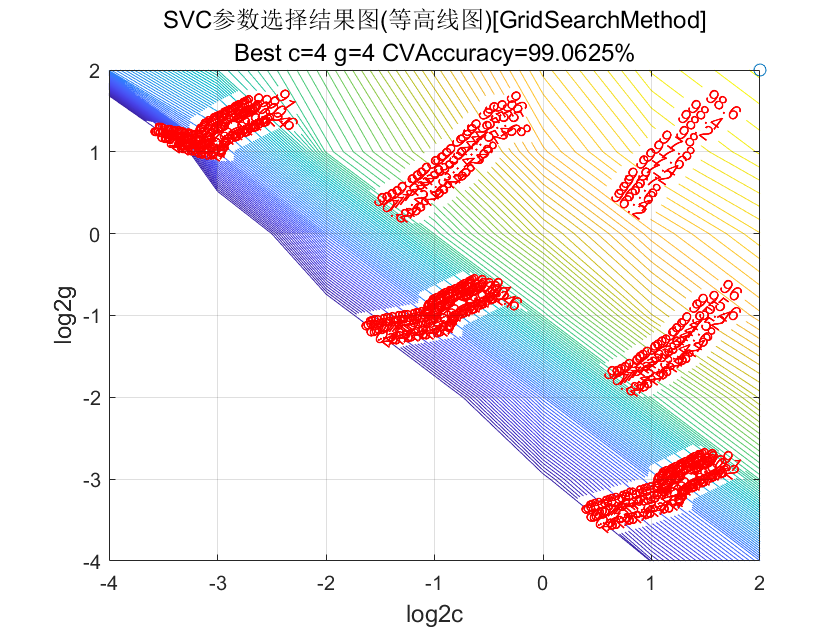

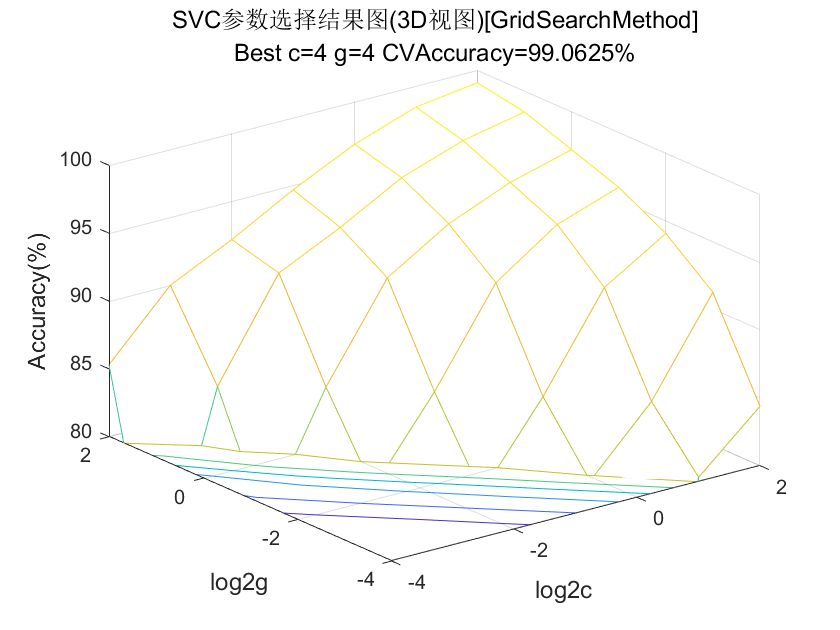

tic
[bestacc, bestc, bestg] = svm_gridsearch(train_label,...
                        train_data,0, 2, 0, 2, 10, 0.1, 0.1, 0.1);

toc

历时 6.411352 秒。


*
optimization finished, #iter = 38
nu = 0.337150
obj = -34.864825, rho = -0.223888
nSV = 53, nBSV = 46
*
optimization finished, #iter = 57
nu = 0.682957
obj = -77.733294, rho = 0.404235
nSV = 102, nBSV = 98
*
optimization finished, #iter = 57
nu = 0.308763
obj = -26.470044, rho = 0.393050
nSV = 48, nBSV = 41
*
optimization finished, #iter = 57
nu = 0.225582
obj = -20.773085, rho = 0.154640
nSV = 36, nBSV = 27
*
optimization finished, #iter = 49
nu = 0.321769
obj = -28.013254, rho = 0.171287
nSV = 49, nBSV = 43
*
optimization finished, #iter = 43
nu = 0.199206
obj = -16.632921, rho = -0.086948
nSV = 32, nBSV = 25
Total nSV = 185
*
optimization finished, #iter = 49
nu = 0.324625
obj = -32.689844, rho = -0.194431
nSV = 51, nBSV = 44
*
optimization finished, #iter = 60
nu = 0.665735
obj = -74.511694, rho = 0.251575
nSV = 99, nBSV = 95
*
optimization finished, #iter = 46
nu = 0.316573
obj = -27.233597, rho = 0.426264
nSV = 50, nBSV = 42
*
optimization finished, #iter = 35
nu = 0.205959
obj

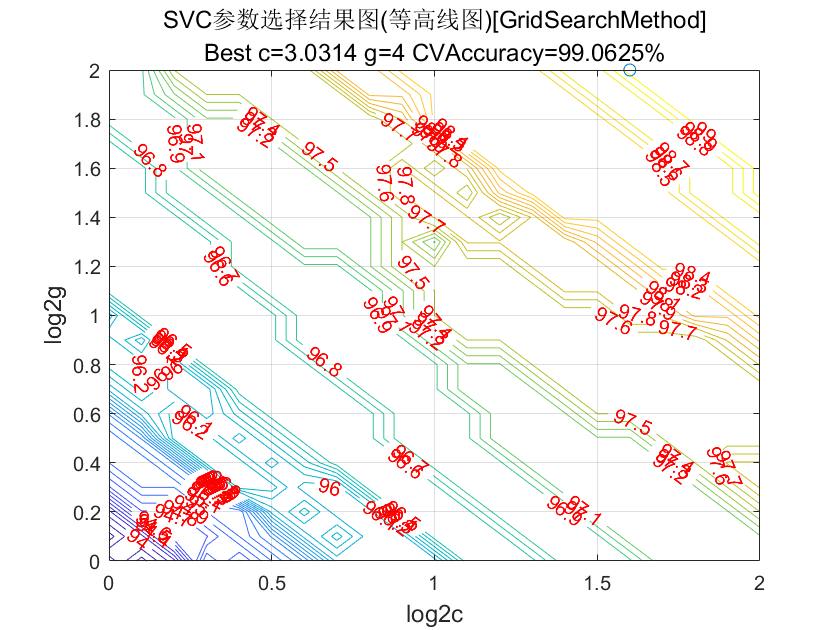

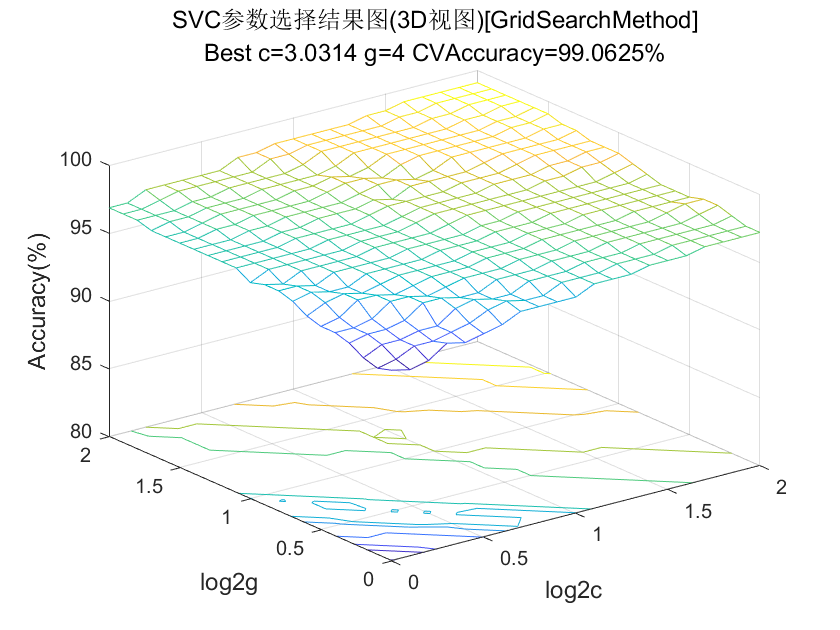

s = 0;
t = 0;
c = bestc;

g = bestg;

历时 33.978563 秒。


options = [' -s ',num2str(s),' -t ',num2str(t),' -c ',num2str(c),' -g ',num2str(g)]; 
model = libsvmtrain(train_label, train_data, options); 

[train_pred_label, train_acc, ~]...
           = libsvmpredict(train_label, train_data, model);
[test_pred_label, test_acc, ~]...
           = libsvmpredict(test_label, test_data, model);

*
optimization finished, #iter = 61
nu = 0.260180
obj = -88.105768, rho = -3.823510
nSV = 46, nBSV = 39
*
optimization finished, #iter = 81
nu = 0.576405
obj = -215.644007, rho = 10.300182
nSV = 96, nBSV = 90
*
optimization finished, #iter = 65
nu = 0.203004
obj = -58.066088, rho = -3.490028
nSV = 37, nBSV = 30
*
optimization finished, #iter = 27
nu = 0.159711
obj = -47.930247, rho = 2.498529
nSV = 27, nBSV = 23
*
optimization finished, #iter = 46
nu = 0.210343
obj = -60.484534, rho = -0.796944
nSV = 35, nBSV = 31
*
optimization finished, #iter = 38
nu = 0.125639
obj = -34.041048, rho = -2.533016
nSV = 23, nBSV = 17
Total nSV = 173


Accuracy = 96.5625% (309/320) (classification)


Accuracy = 95% (76/80) (classification)
